**This section of the file loads data on house price variation in percentages for some European nations. **The data is taken from Eurostat. The 'time' variable simulates a ficticious timeline against which data will be plotted. 

A drop down menu is added for making a scatterplot and fitting a line for each nation in the original table.

The purpose of this work is to practice basic Matlab knowledge. 

load housecorr % table of data on house prices
housecorr

housecorr = 9×45 table
      VarName1       Q1       Q2       Q3       Q4       Q5       Q6       Q7      Q8      Q9     Q10     Q11     Q12     Q13     Q14     Q15     Q16     Q17    Q18    Q19    Q20     Q21     Q22     Q23     Q24     Q25     Q26     Q27    Q28    Q29    Q30    Q31    Q32    Q33     Q34    Q35     Q36     Q37     Q38

dats=housecorr{:,2:end};
names=housecorr{:,1};
nation=names(5)

nation = 1×1 cell array
    {'Germany '}


log1=strcmp(nation,names)

log1 = 9×1 logical array
   0
   0
   0
   0
   1
   0
   0
   0
   0


% if string comparison=1, we find the index
index=find(log1);
time=linspace(12,23,44) % setting the time x-axis

time =    12.0000   12.2558   12.5116   12.7674   13.0233   13.2791   13.5349   13.7907   14.0465   14.3023   14.5581   14.8140   15.0698   15.3256   15.5814   15.8372   16.0930   16.3488   16.6047   16.8605   17.1163   17.3721   17.6279   17.8837   18.1395   18.3953   18.6512   18.9070   19.1628   19.4186   19.6744   19.9302   20.1860   20.4419   20.6977   20.9535   21.2093   21.4651   21.7209   21.9767   22.2326   22.4884   22.7442   23.0000


nationdata=dats(index,:);
scatter(time,nationdata,'k','filled')
grid on
axis tight
xlabel('Years')
ylabel('House price variation in %')
title(nation + " real estate prices")
disp('Fitting a line for prices trend')

Fitting a line for prices trend


% degree 1 of polynomial
[polynom,~,scal]=polyfit(time,nationdata,1)

polynom =     1.6926    5.9318


scal =    17.5000
    3.2860


yfitted=polyval(polynom,time,[],scal)

yfitted =     3.0988    3.2306    3.3623    3.4941    3.6259    3.7576    3.8894    4.0212    4.1529    4.2847    4.4165    4.5482    4.6800    4.8118    4.9436    5.0753    5.2071    5.3389    5.4706    5.6024    5.7342    5.8659    5.9977    6.1295    6.2612    6.3930    6.5248    6.6565    6.7883    6.9201    7.0519    7.1836    7.3154    7.4472    7.5789    7.7107    7.8425    7.9742    8.1060    8.2378    8.3695    8.5013    8.6331    8.7648


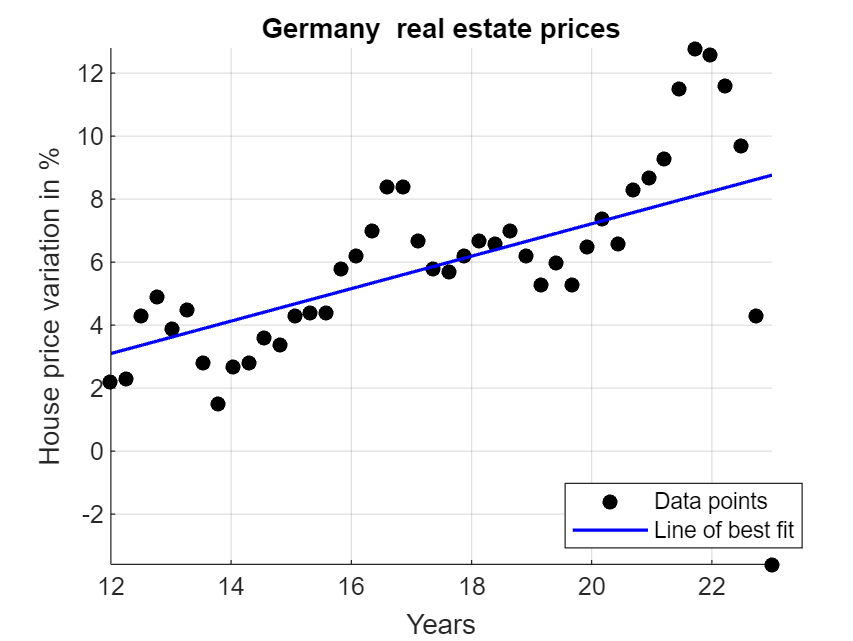

hold on;
plot(time,yfitted,'b','linewidth',1.3)
legend('Data points','Line of best fit')
legend("Position", [0.68906,0.15522,0.225,0.082143])
hold off;

**This code section uses a while loop to compute a Taylor Series approximation for a specific function:**

**Computing Taylor Series for f(x)=e^x:**

disp('Taylor series computation for e^x')

Taylor series computation for e^x


x=2 % input argument

x = 2

n=0; % starting point
t=1; % term 1 of taylor sum
tseries=0; % taylor sum
while n<=30 && abs(t)>0.0001
    if n==30 && abs(t)>=0.0001
        errordlg("Se necesitan más de 30 terminos","Error")
    else 
        t=(x^n)/factorial(n);
        tseries=tseries+t;
        n=n+1;
    end 
end 
tseries 

tseries = 7.3890

n % number of iterations should be 30

n = 12